clear all;
close all;

### Valeurs nominal de la MCC2:

 Un = 60V; In = 2A ;Nn = 3350 tr/mn 

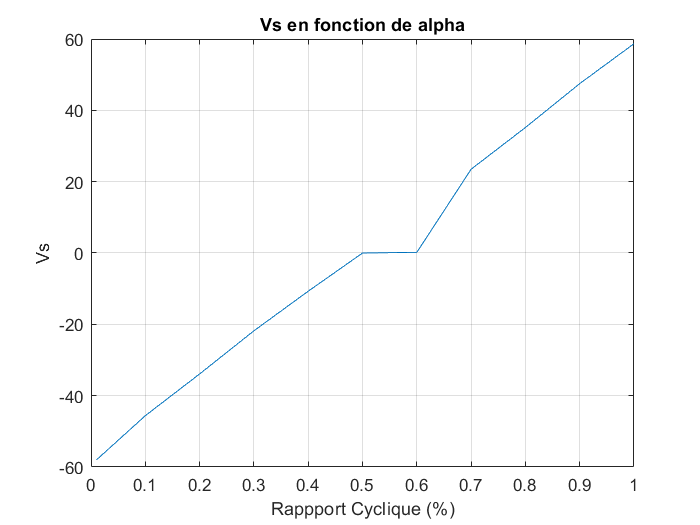

k = 65.6e-3;R=0.552;%a vérifier
Ue=60;
alpha=[0.01 0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1];
Vs=[-58 -45.6 -33.9 -21.8 -10.7 0 0.19 23.5 35.2 47.5 58.7];
N=[-3900 -3100 -2270 -1410 -650 0 685 1540 2313 3153 3930];

plot(alpha,Vs);
title('Vs en fonction de alpha')
xlabel('Rappport Cyclique (%)'); ylabel('Vs')
grid on

% 
% Vsth=(2.*alpha-1)*Ue;
% N_th = (Vsth-R*Is)/(2*k)*9.5492965855137;

% plot(alpha,N,alpha,N_th);
% title('N pratique et N theorique en fonction de alpha')
% xlabel('Rappport Cyclique (%)'); ylabel('N,','Nth')
% grid on

influence de la tension d’alimentation UE

Dans le cas où le rapport cyclique est fixe et la tension d'alimentation varie, alors la vitesse de rotation du moteur variera en fonction de Ve : 

Vs = (2a-1)Ve et N = ...Vs, or, a fixe et Ve varie donc N varie en fonction de Ve.

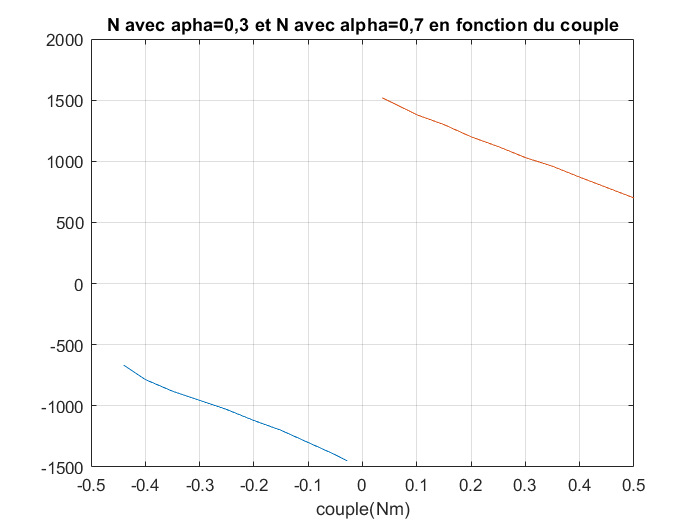

Couple_03 = [0.028 0.05 0.1 0.15 0.2 0.25 0.3 0.35 0.4 0.44].*-1; %négatif
Couple_07 = [0.036 0.05 0.1 0.15 0.2 0.25 0.3 0.35 0.4 0.5];

N_03=[1450 1400 1300 1200 1120 1030 955 880 785 666].*-1;
N_07=[1520 1490 1380 1300 1200 1120 1030 959 870 700];

plot(Couple_03,N_03,Couple_07,N_07)
title('N avec apha=0,3 et N avec alpha=0,7 en fonction du couple')
xlabel('couple(Nm)'); 
%ylabel('N_03,','N_07')
%legend("Alpha=0.3","Alpha=0.7")
grid on

% N_th_2 =(60*I)/(Couple*pi);
% %Faire tracé théorique

### Alimentation en vitesse variable d’un moteur à courant continu avec un hacheur 2 quadrants 

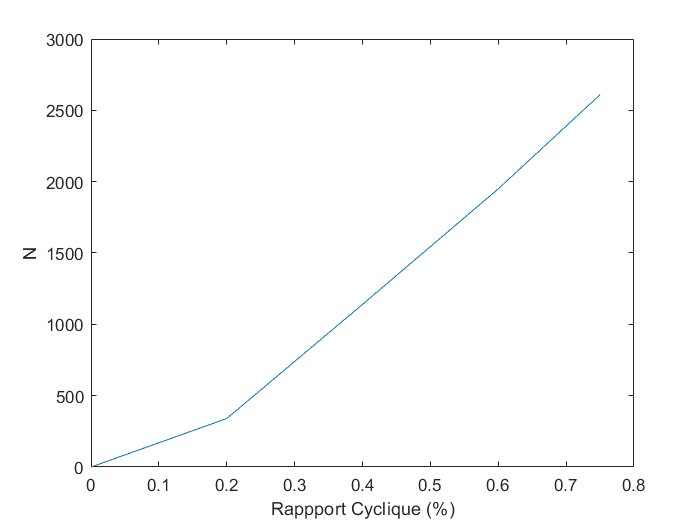

alpha_2Q=[0 0.2 0.4 0.6 0.75];
Ue = 60; Is=2;
Vs1=[0 11.06 23 35.3 45.1];
N_2Q=[0 340 1140 1950 2610];
plot(alpha_2Q,N_2Q)
xlabel('Rappport Cyclique (%)'); ylabel('N')

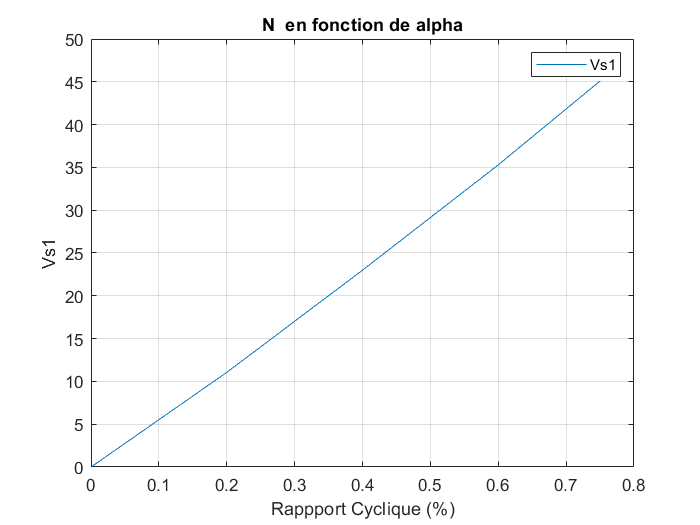


plot(alpha_2Q,Vs1)
title('N  en fonction de alpha')
xlabel('Rappport Cyclique (%)'); ylabel('Vs1')
legend('Vs1')
grid on

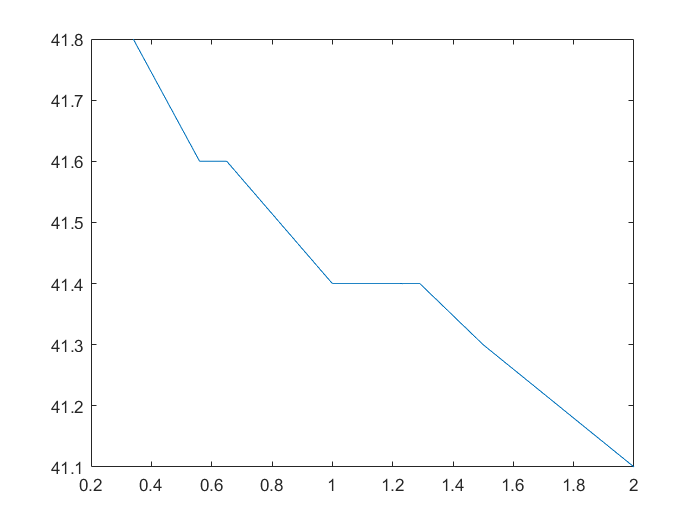

Is1_2Qb=[0.34 0.56 0.65 1 1.29 1.5 2];
Vs1_2Qb=[41.8 41.6 41.6 41.4 41.4 41.3 41.1];

Couple_2Qb=[-0.018 -0.049 -0.061 -0.1 -0.146 -0.176 -0.242];
N_2Qb=[2797 2722 2691 2592 2522 2464 2334];

plot(Is1_2Qb,Vs1_2Qb)

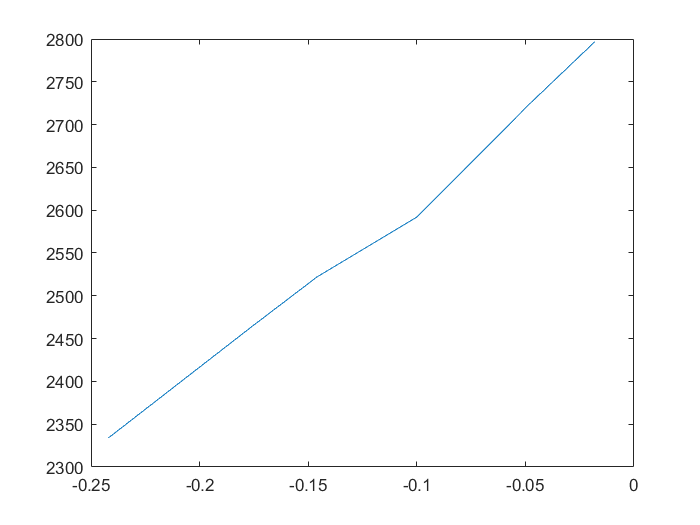

plot(Couple_2Qb,N_2Qb)

### Fonctionnement du hacheur 2 quadrants avec un courant de sortie négatif par la méthode d'opposition

# interdit de dépasser une valeur maximale de 0,40 pour le rapport cyclique α2.

alpha1=[0 0.2 0.4 0.6 0.8 1];
Vs1_opp=[];
N = [2805 ]
% Vs2_opp=[];
% 
% Is1_03=[-2 -1.5 -1 -0.5 0];%prendre alpha=0.3
% Is1_07=[];%prendre alpha=0.7
% Vs1_opp2=[];
% 
% couple_2Q=[]; %A faire varier
N_opp=[]; %a mesurer

plot(alpha1,Vs1_opp,alpha1,Vs2_opp);

Unrecognized function or variable 'alpha1'.

title('Vs1 et Vs2 en fonction de alpha')
xlabel('Rappport Cyclique (%)'); ylabel('Vs1,','Vs2')
legend("Vs1","Vs2")
grid on

plot(Vs1_opp2,Is1_03);
title('Vs1 en fonction de Is1')
xlabel('Courant de sortie (A)'); %ylabel('Vs1,','Vs2')
legend("Vs1")
grid on

# bilan des puissances